## Import Data

Import training and validation data.

imdsTrain = imageDatastore("F:\InceptionV3\Data299","IncludeSubfolders",true,"LabelSource","foldernames");
[imdsTrain, imdsValidation] = splitEachLabel(imdsTrain,0.7,"randomized");

% % Load Network
load trainedNetwork_1

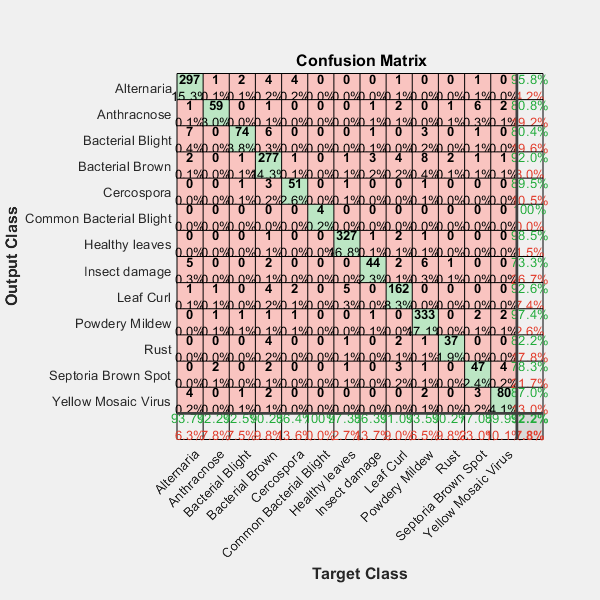

% Classify Validation Images
[testData]=splitEachLabel(imdsTrain,0.3,'randomize');
allclass=[];
for ii=1:length(testData.Labels)
    I=readimage(testData,ii);
    % % Done Classification
       class=classify(trainedNetwork_1,I);
       % figure(5),
       % subplot(8,8,ii)
       % imshow(I)
       % title(char(class))
       allclass=[allclass class];
end
figure,plotconfusion(allclass,testData.Labels')

% layer=7;
YValidation=testData.Labels;
Ypred=allclass;
accuracy=sum(Ypred==YValidation')/numel(YValidation);
Cpredicted=allclass;
C=confusionmat(YValidation,Cpredicted);
OverallAccTst=sum(YValidation==Cpredicted)/length(Cpredicted);
Acc=zeros(2,1);
Sens=zeros(2,1);
Spec=zeros(2,1);
Prec=zeros(2,1);
F1Sc=zeros(2,1);
FPR=zeros(2,1);
MCC=zeros(2,1);
ERate=zeros(2,1);
for i=1:length(C)
    TP=C(i,i);
    TN=sum(C(:))-sum(C(:,i))-sum(C(i,:))+C(i,i);
    FP=sum(C(:,i))-C(i,i);
    FN=sum(C(i,:))-C(i,i);
    Acc(i)=(TP+TN)/(TP+TN+FP+FN);
    Sens(i)=TP/(TP+FN);
    Spec(i)=TN/(FP+TN);
    Prec(i)=TP/(TP+FP);
    F1Sc(i)=2*TP/(2*TP+FP+FN);
    S=(TP+FN)/sum(C(:));
    P=(TP+FP)/sum(C(:));
    MCC(i)=(TP/sum(C(:))-S*P)/sqrt(S*P*(1-S)*(1-P));
    ERate(i)=1-Acc(i);
    FPR(i)=1-Spec(i);
end
disp('Accuracy')

Accuracy


fprintf('The acc is : %f \n',Acc);

The acc is : 0.983016 
The acc is : 0.990221 
The acc is : 0.987648 
The acc is : 0.972208 
The acc is : 0.992795 
The acc is : 1.000000 
The acc is : 0.992795 
The acc is : 0.988163 
The acc is : 0.985075 
The acc is : 0.983531 
The acc is : 0.993824 
The acc is : 0.986104 
The acc is : 0.989192 



disp('Sensitivity')

Sensitivity


 sprintf('The Sensitivity is : %f \n', Sens)

ans =     'The Sensitivity is : 0.958065 
     The Sensitivity is : 0.808219 
     The Sensitivity is : 0.804348 
     The Sensitivity is : 0.920266 
     The Sensitivity is : 0.894737 
     The Sensitivity is : 1.000000 
     The Sensitivity is : 0.984940 
     The Sensitivity is : 0.733333 
     The Sensitivity is : 0.925714 
     The Sensitivity is : 0.973684 
     The Sensitivity is : 0.822222 
     The Sensitivity is : 0.783333 
     The Sensitivity is : 0.869565 
     '


disp('Specificity')

Specificity


sprintf('The Specificity is: %f \n', Spec)

ans =     'The Specificity is: 0.987753 
     The Specificity is: 0.997326 
     The Specificity is: 0.996759 
     The Specificity is: 0.981730 
     The Specificity is: 0.995758 
     The Specificity is: 1.000000 
     The Specificity is: 0.994413 
     The Specificity is: 0.996283 
     The Specificity is: 0.990950 
     The Specificity is: 0.985634 
     The Specificity is: 0.997893 
     The Specificity is: 0.992565 
     The Specificity is: 0.995138 
     '


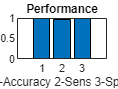

figure
bar([Acc(1) Sens(1) Spec(1) F1Sc(1) Prec(1) ])
xlabel('1-Accuracy 2-Sens 3-Spec 4-F1Sc 5-Prec')
title('Performance');

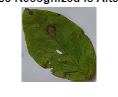


% Read image for Classification
[filename,pathname]=uigetfile('*.*','Select the Input Image');
file=strcat(pathname,filename);
I=imread(file);
figure
imshow(I)
% Classifiy the image using the network
label=classify(trainedNetwork_1,I);
title(['Disease Recognized is ', char(label)])